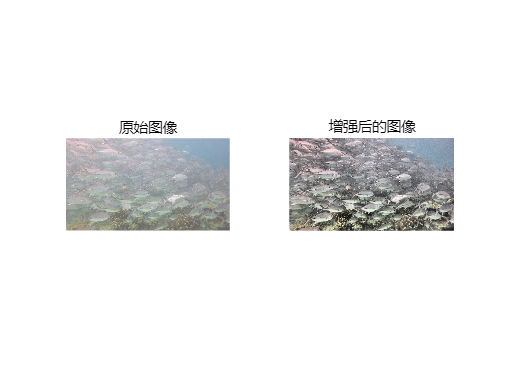

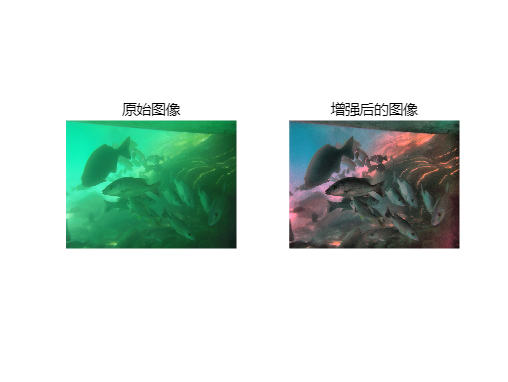

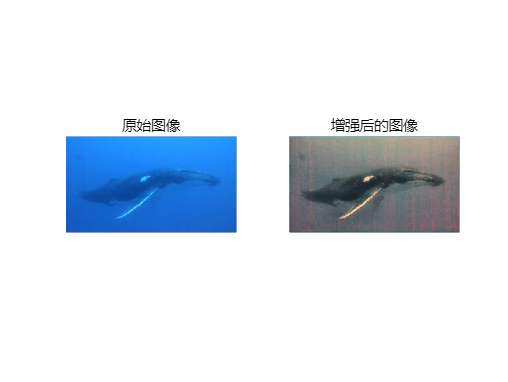

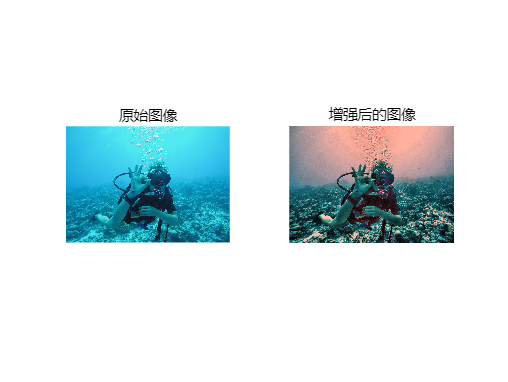

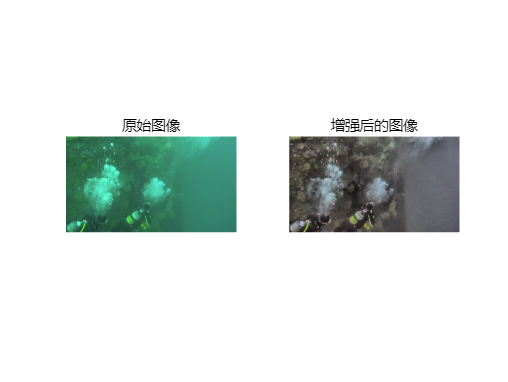

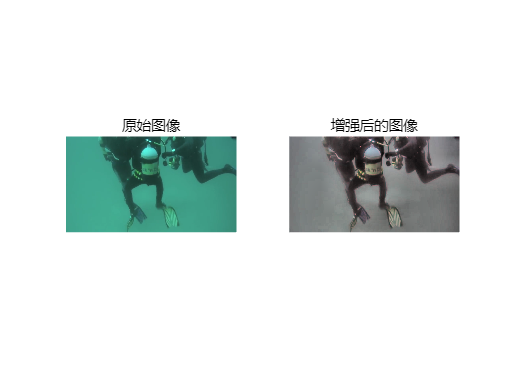

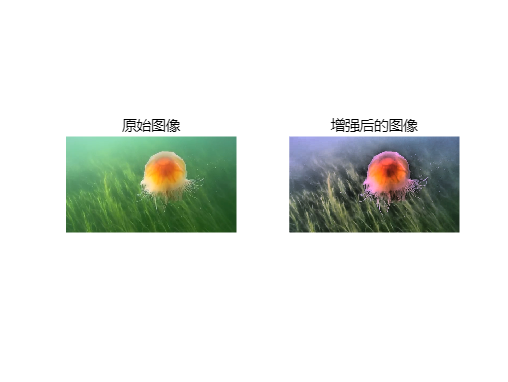

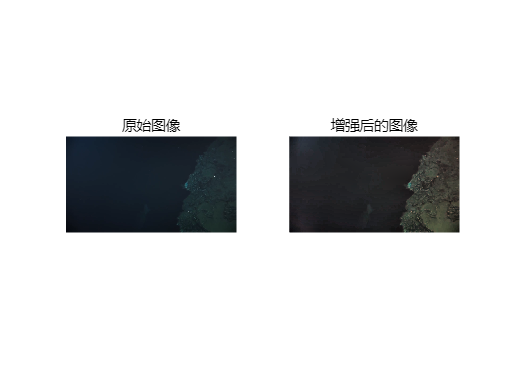

% 读取图像
for i = 1:12
    fileName = sprintf('test_%03d.png', i);
    t = imread(fileName); 

    figure;
    subplot(1,2,1);
    imshow(t), title('原始图像');
    t_hsv = rgb2hsv(t);
    V = t_hsv(:,:,3);
    V_eq = adapthisteq(V, 'NumTiles', [8 8], 'ClipLimit', 0.01);  
    t_hsv(:,:,3) = V_eq; 
    t_eq = hsv2rgb(t_hsv);
    
    % 颜色校正（灰度世界假设）
    mean_r = mean2(t_eq(:,:,1));
    mean_g = mean2(t_eq(:,:,2));
    mean_b = mean2(t_eq(:,:,3));
    mean_gray = (mean_r + mean_g + mean_b) / 3;
    adj_r = mean_gray / (mean_r + eps);
    adj_g = mean_gray / (mean_g + eps);
    adj_b = mean_gray / (mean_b + eps);
    t_eq(:,:,1) = t_eq(:,:,1) * adj_r;
    t_eq(:,:,2) = t_eq(:,:,2) * adj_g;
    t_eq(:,:,3) = t_eq(:,:,3) * adj_b;
    t_eq = min(max(t_eq, 0), 1);
    t_eq = im2double(t_eq);
    
    % 显示增强后的图像
    subplot(1,2,2);
    imshow(t_eq), title('增强后的图像');
end